**Step 0**: Preprocesseing

clearvars
clc
%run_preprocessing

Start logging to this file

% Create folder for models if it doesn't exist
if ~isfolder('out/easer')
    mkdir('out/easer');
end
diary('out/easer/log.txt'); 
diary on;

**Step 1**: Load Preprocessed Data (if already done before)

global R_train test_u test_i MAXOBJ
load('out/train.mat');   % R_train, train_u, train_i, train_ctx
load('out/val.mat');     % val_u, val_i, val_ctx
load('out/test.mat');    % test_u, test_i, test_ctx

**Step 2**: Train Implicit MF through different variables

and

**Step 3: **Evaluation (Recall@20, NDCG@20)

MAXOBJ = 30;
fprintf('[%s] Run Started\n', string(datetime('now')));

[05-Sep-2025 13:18:26] Run Started


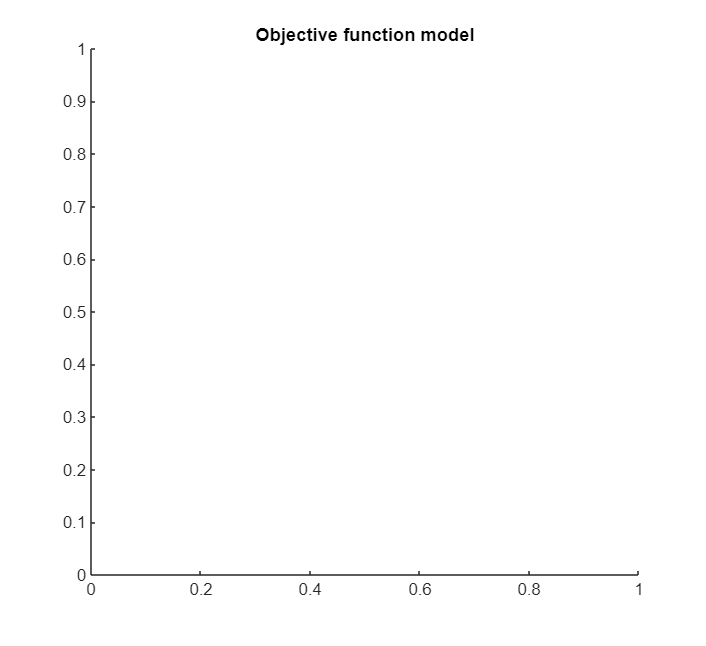

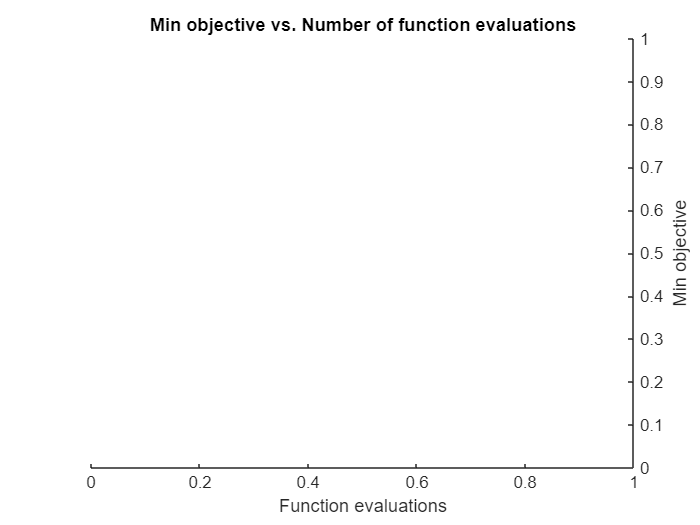

[05-Sep-2025 13:18:27][1/30] lambda=0.4175


Error using eye
Maximum variable size allowed on the device is exceeded.

Error in easer (line 29)
I = eye(num_items, 'gpuArray'); 

Error in easermain>objectiveFunction (line 50)
    [U, V] = easer(R_train, lambda);

Error in 


% Only lambda is optimized for EASER
vars = [
    optimizableVariable('lambda', [0.01, 1])
];



% Run Bayesian Optimization
resultsBO = bayesopt(@objectiveFunction, ...
    vars, ...
    'MaxObjectiveEvaluations', MAXOBJ, ...
    'IsObjectiveDeterministic', true, ...
    'Verbose', 1);


diary off;

**objective function : **which is created to optimize the best output

function score = objectiveFunction(x)
    % Global variables for data
    global R_train test_u test_i MAXOBJ
    persistent row_idx count results

    if isempty(row_idx)
        row_idx = 1;
        count = 0;
        results = zeros(MAXOBJ, 3); % Only lambda, recall20, ndcg20
    end

    % Extract hyperparameters from input struct
    lambda = x.lambda;

    fprintf('[%s][%d/%d] lambda=%.4f\n', ...
        string(datetime('now')), row_idx, MAXOBJ, lambda);

    % Training with EASER
    [U, V] = easer(R_train, lambda);

    % Evaluation
    [recall20, ndcg20] = evaluate(U, V, test_u, test_i, R_train);

    % Logging results
    results(row_idx, :) = [lambda, recall20, ndcg20];
    count = count + 1;

    % Save results to disk after each run
    save(fullfile('out/easer', 'results.mat'), 'results', '-v7');

    fprintf('[%s][%d/%d] lambda=%.4f → Recall@20=%.4f, NDCG@20=%.4f\n', ...
        string(datetime('now')), row_idx, MAXOBJ, lambda, recall20, ndcg20);
    drawnow;

    % Save model
    model_name = sprintf('model%d_lambda%.4f.mat', row_idx, lambda);
    save(fullfile('out/easer', model_name), 'U', 'V');

    % Increment row index
    row_idx = row_idx + 1;

    % Return negative product for minimization
    score = -recall20 * ndcg20;
end
